clear all;
close all;
clc;

## Partie 1

Chargement des données

load("ECG_TP_effort.mat");
load("ECG_TP_repos.mat");

## Partie 2

Initialisation : les deux fichiers ont exactement la meme duree, donc pas besoin de creer des variables separees.

fe = 1000;                      % Frequence d'echantillonnage en Hz
N = length(X_ECG_Eff);          % Taille du vecteur
t = linspace(0, N/fe, N);       % Echelle temporelle

Affichage des series temporelles

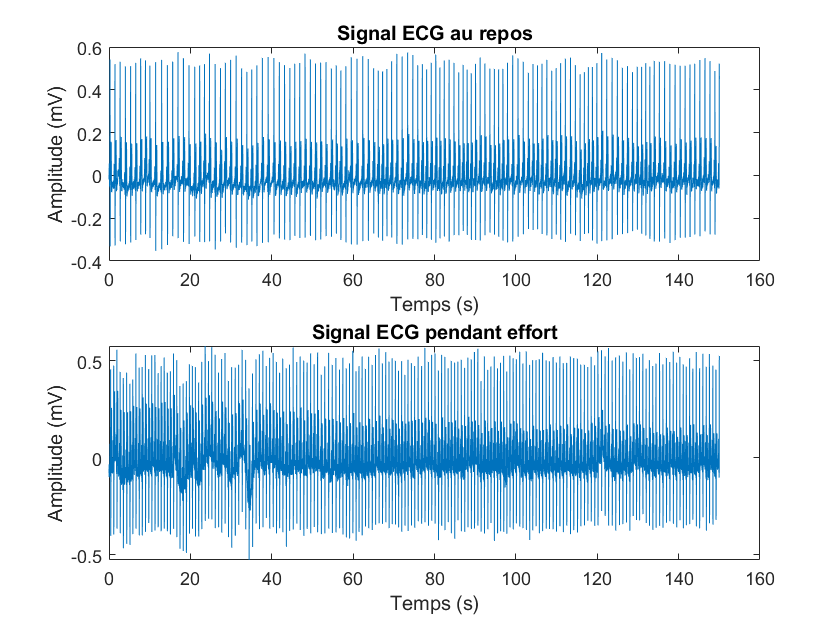

figure(1);
subplot(2, 1, 1); plot(t, X_ECG_Rep);
xlabel('Temps (s)'); ylabel('Amplitude (mV)'); title('Signal ECG au repos')
subplot(2, 1, 2); plot(t, X_ECG_Eff);
xlabel('Temps (s)'); ylabel('Amplitude (mV)'); title('Signal ECG pendant effort')

## Partie 3

NFFT = 2 .^ nextpow2(N);                   % Next power of 2 from length of x
FFT_ECG_Rep = fft(X_ECG_Rep, N);        % TF repos
FFT_ECG_Eff = fft(X_ECG_Eff, N);        % TF effort
f = fe/2 * linspace(0, 1, NFFT/2);         % Semie-echelle fr�quentielle

Affichage des spectres (module uniquement, pas la phase)

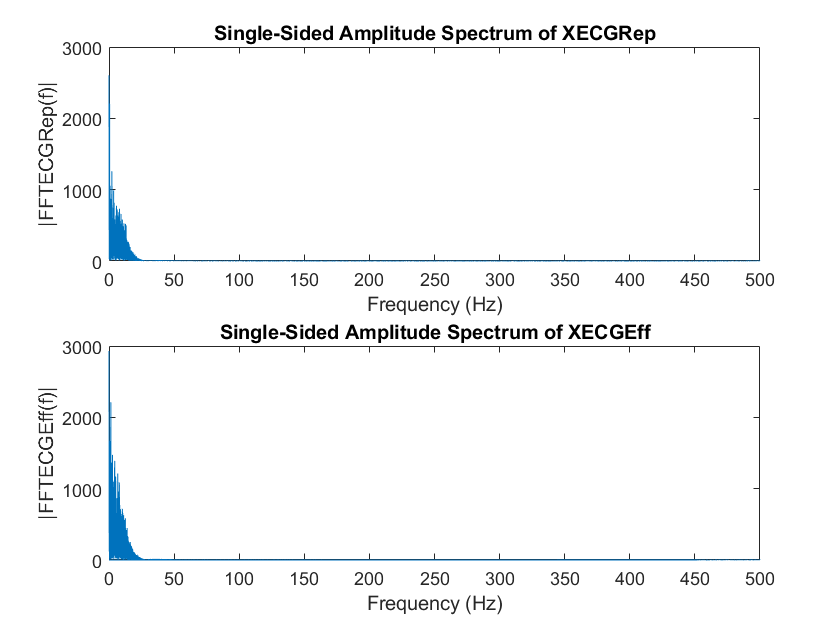

figure(2);
subplot(2, 1, 1); plot(f, 2*abs(FFT_ECG_Rep(1:NFFT/2)));
xlabel('Frequency (Hz)'); ylabel('|FFTECGRep(f)|');
title('Single-Sided Amplitude Spectrum of XECGRep');
subplot(2, 1, 2); plot(f, 2*abs(FFT_ECG_Eff(1:NFFT/2)));
xlabel('Frequency (Hz)'); ylabel('|FFTECGEff(f)|');
title('Single-Sided Amplitude Spectrum of XECGEff');

## Partie 4: Extraction de la série temporelle RR

### Etape 1 : Seuillage

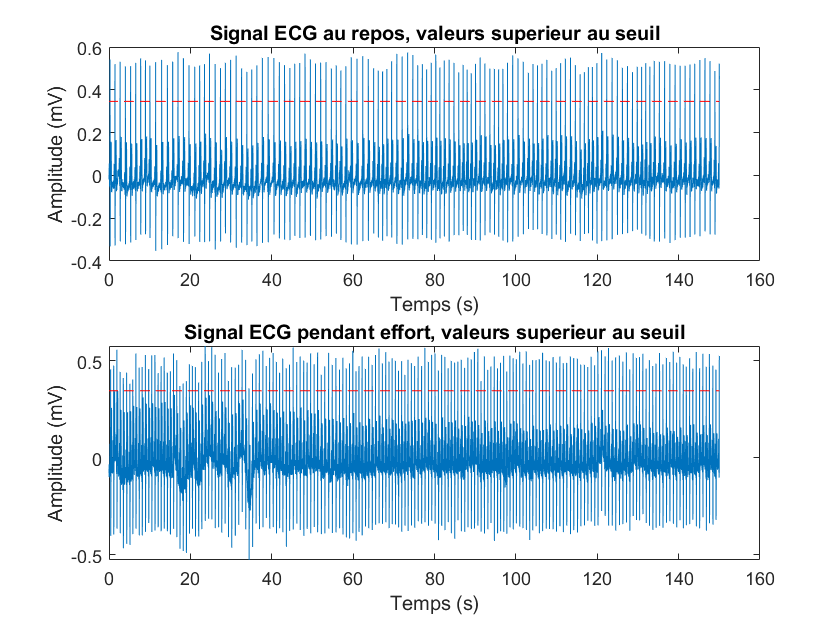

seuil_Rep = 0.6 * max(X_ECG_Rep);
seuil_Eff = 0.6 * max(X_ECG_Eff);
figure(3);
subplot(2, 1, 1); plot(t, X_ECG_Rep); hold on; plot(t, seuil_Rep * ones(1, length(t)), "--r" );
xlabel('Temps (s)'); ylabel('Amplitude (mV)'); title('Signal ECG au repos, valeurs superieur au seuil')
subplot(2, 1, 2); plot(t,X_ECG_Eff); hold on; plot(t, seuil_Eff * ones(1, length(t)), "--r" );
xlabel('Temps (s)'); ylabel('Amplitude (mV)'); title('Signal ECG pendant effort, valeurs superieur au seuil')

### Etape 2

#### Vecteur logique repos

Diag_ECG_Rep = zeros(size(X_ECG_Rep));
for i = 1:length(Diag_ECG_Rep)
    if X_ECG_Rep(i) > seuil_Rep
        Diag_ECG_Rep(1, i) = 1;
    else
        Diag_ECG_Rep(1, i) = 0;
    end
end

#### Vecteur logique effort

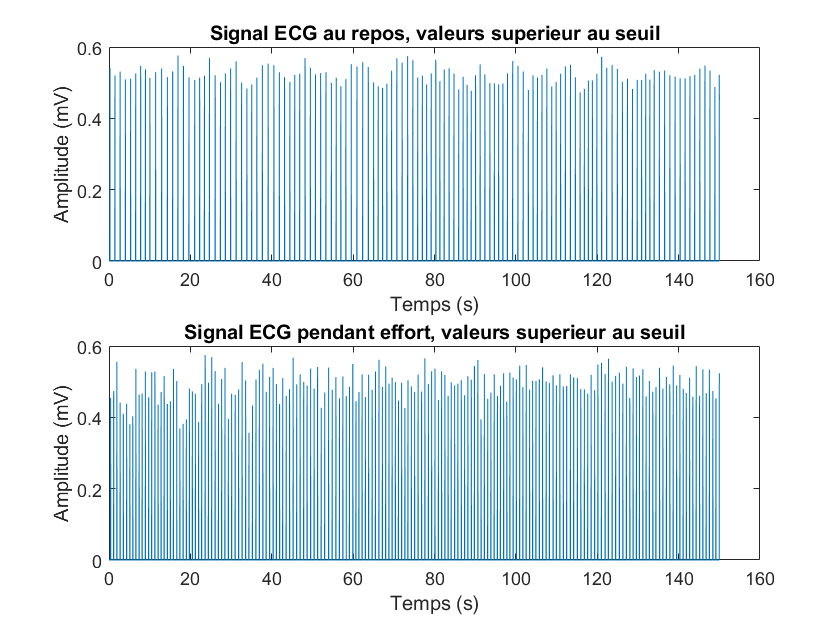

Diag_ECG_Eff = zeros(size(X_ECG_Rep));
for i = 1:length(Diag_ECG_Eff)
    if X_ECG_Eff(i) > seuil_Eff
        Diag_ECG_Eff(1, i) = 1;
    else
        Diag_ECG_Eff(1, i) = 0;
    end
end
figure(4);
subplot(2, 1, 1); plot(t, Diag_ECG_Rep .* X_ECG_Rep);
xlabel('Temps (s)'); ylabel('Amplitude (mV)'); title('Signal ECG au repos, valeurs superieur au seuil')
subplot(2, 1, 2); plot(t, Diag_ECG_Eff .* X_ECG_Eff);
xlabel('Temps (s)'); ylabel('Amplitude (mV)'); title('Signal ECG pendant effort, valeurs superieur au seuil')

## Etapes 3 :

### Repos

Diff_Diag_ECG_Rep_P = find(diff(Diag_ECG_Rep) == 1); Diff_Diag_ECG_Rep_P(end) = [];
Diff_Diag_ECG_Rep_N = find(diff(Diag_ECG_Rep) == -1);
A_Rep = [];
B_Rep = [];
for k = 1 : length(Diff_Diag_ECG_Rep_P)
    [A_Rep(k), B_Rep(k)] = max(X_ECG_Rep(Diff_Diag_ECG_Rep_P(1, k) : Diff_Diag_ECG_Rep_N(1, k)));
    B_Rep(k) = B_Rep(k) + Diff_Diag_ECG_Rep_P(1, k);
end
Peak_ECG_Rep = zeros(size(X_ECG_Rep));
Peak_ECG_Rep(B_Rep) = X_ECG_Rep(B_Rep);

### Effort

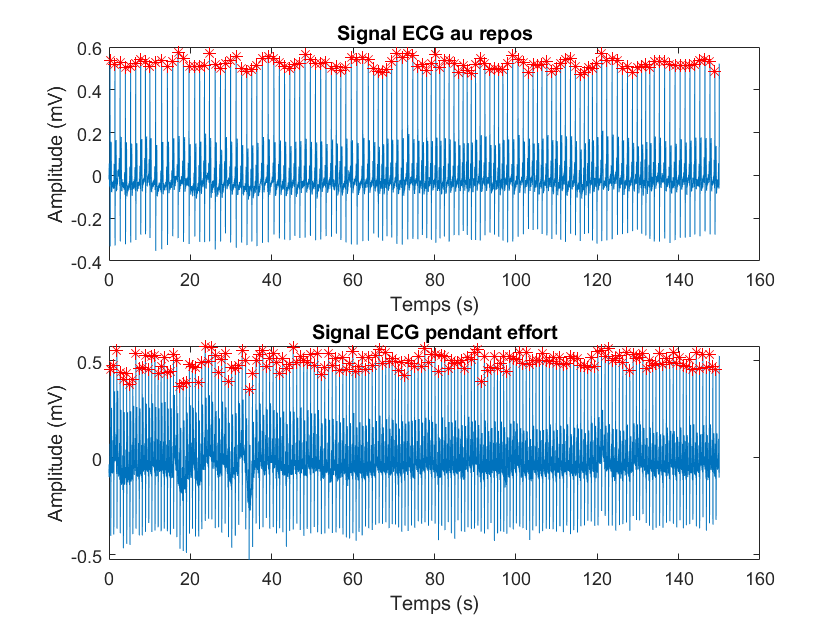

Diff_Diag_ECG_Eff_P = find(diff(Diag_ECG_Eff) == 1); Diff_Diag_ECG_Eff_P(end) = [];
Diff_Diag_ECG_Eff_N = find(diff(Diag_ECG_Eff) == -1);
A_Eff = [];
B_Eff = [];
for k = 1 : length(Diff_Diag_ECG_Eff_P)
    [A_Eff(k), B_Eff(k)] = max(X_ECG_Eff(Diff_Diag_ECG_Eff_P(1, k) : Diff_Diag_ECG_Eff_N(1, k)));
    B_Eff(k) = B_Eff(k) + Diff_Diag_ECG_Eff_P(1, k);
end
Peak_ECG_Eff = zeros(size(X_ECG_Eff));
Peak_ECG_Eff(B_Eff) = X_ECG_Eff(B_Eff);

figure(1);  % Reprise de la figure 1
subplot(2, 1, 1); hold on; plot(t(B_Rep), Peak_ECG_Rep(B_Rep), 'r*');
subplot(2, 1, 2); hold on; plot(t(B_Eff), Peak_ECG_Eff(B_Eff), 'r*');

## Etape 4

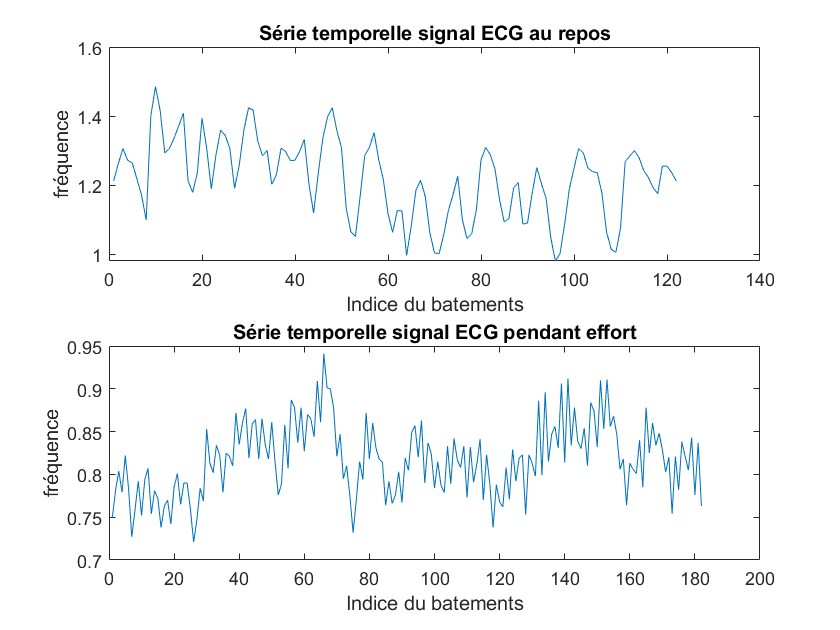

RR_ECG_Rep = diff(t(B_Rep));
RR_ECG_Eff = diff(t(B_Eff));
figure(5);
subplot(2, 1, 1); plot(RR_ECG_Rep);
xlabel('Indice du batements'); ylabel('fréquence'); title('Série temporelle signal ECG au repos')
subplot(2, 1, 2); plot(RR_ECG_Eff);
xlabel('Indice du batements'); ylabel('fréquence'); title('Série temporelle signal ECG pendant effort')

## Partie 5

fc1 = 0.4;    % Fr�quence de coupure haute
fc2 = 0.04;   % Fr�quence de coupure basse
fe_RR = 1;    %Freq d'echantillonnage theorique de la s�rie RR

Filtarge des series RR entre 0.04 Hz ET 0.4 Hz

RR_ECG_Rep_filtre = bandf(RR_ECG_Rep, (fc1*2)/fe_RR, (fc2*2)/fe_RR);
RR_ECG_Eff_filtre = bandf(RR_ECG_Eff, (fc1*2)/fe_RR, (fc2*2)/fe_RR);

TF des signaux

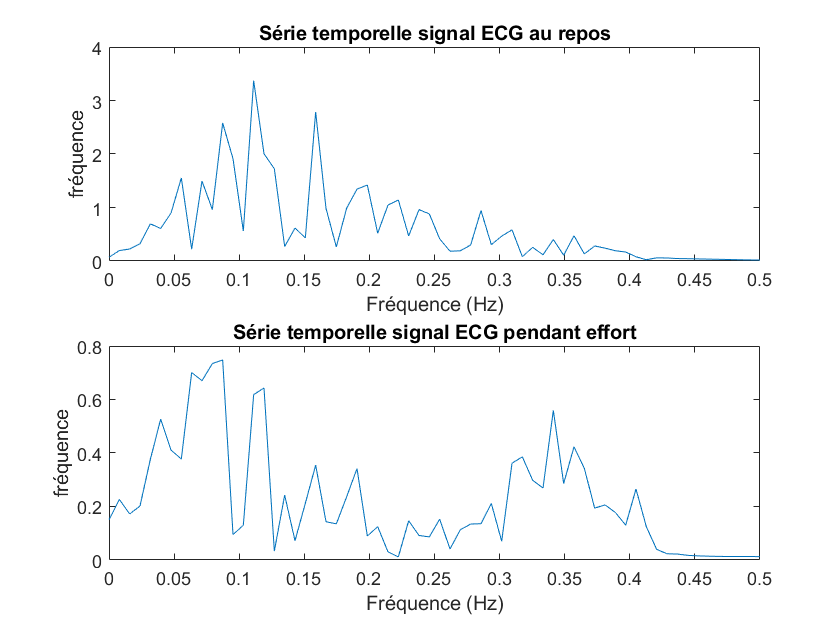

nb_points_fft = 128;
f = fe_RR/2 * linspace(0, 1, nb_points_fft/2);
TF_RR_ECG_Rep_filtre = fft(RR_ECG_Rep_filtre, nb_points_fft);
TF_RR_ECG_Eff_filtre = fft(RR_ECG_Eff_filtre, nb_points_fft);
figure(6);
subplot(2, 1, 1); plot(f, abs(TF_RR_ECG_Rep_filtre(1:nb_points_fft / 2)));
xlabel('Fréquence (Hz)'); ylabel('fréquence'); title('Série temporelle signal ECG au repos')
subplot(2, 1, 2); plot(f, abs(TF_RR_ECG_Eff_filtre(1:nb_points_fft / 2)));
xlabel('Fréquence (Hz)'); ylabel('fréquence'); title('Série temporelle signal ECG pendant effort')

## Partie 6

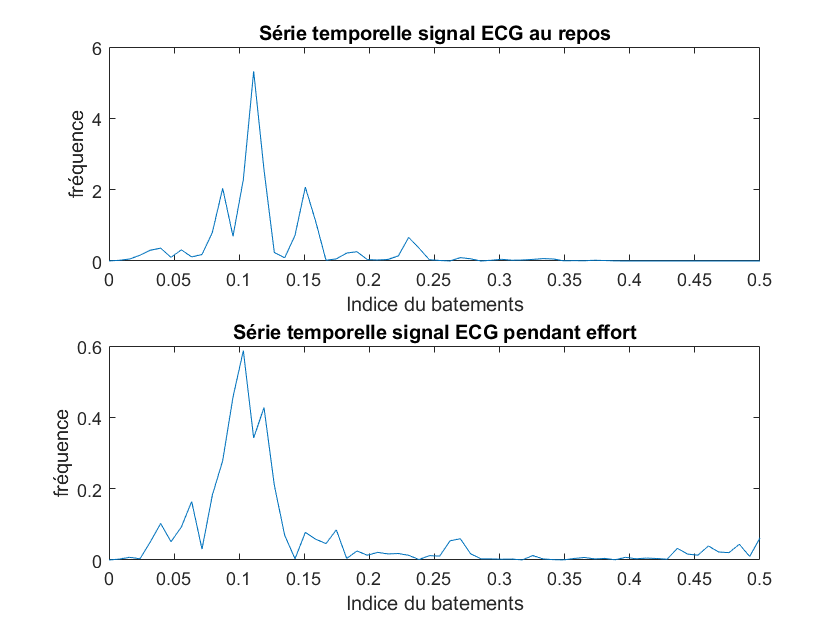

PSD_RR_ECG_Rep_filtre = abs(fft(RR_ECG_Rep_filtre .* hann(length(RR_ECG_Rep_filtre))' )) .^ 2;
PSD_RR_ECG_Eff_filtre = abs(fft(RR_ECG_Eff_filtre .* hann(length(RR_ECG_Eff_filtre))' )) .^ 2;

figure(7);
subplot(2, 1, 1); plot(f, PSD_RR_ECG_Rep_filtre(1:nb_points_fft / 2));
xlabel('Indice du batements'); ylabel('fréquence'); title('Série temporelle signal ECG au repos')
subplot(2, 1, 2); plot(f, PSD_RR_ECG_Eff_filtre(1:nb_points_fft / 2));
xlabel('Indice du batements'); ylabel('fréquence'); title('Série temporelle signal ECG pendant effort')